# 神经网络预测体脂率

如何根据年龄、身高、腰围等13项身体属性来判断体脂率？

导入特征数据

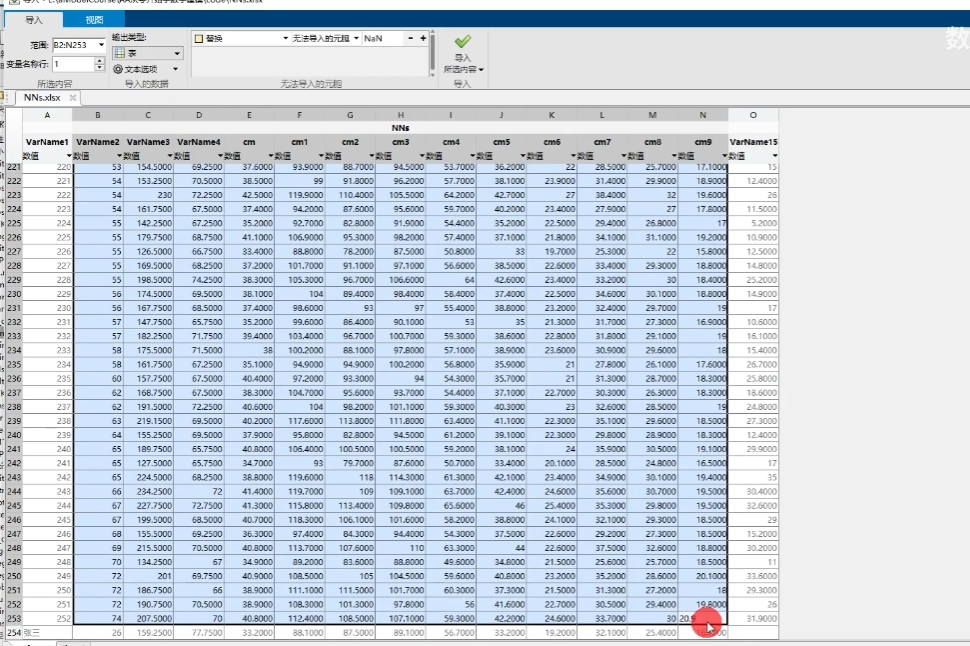

修改输出类型

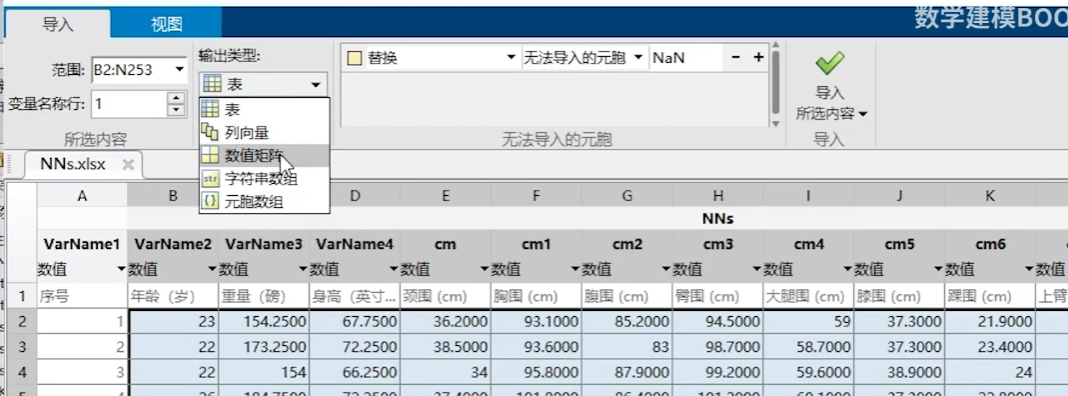

修改输出变量名称为X

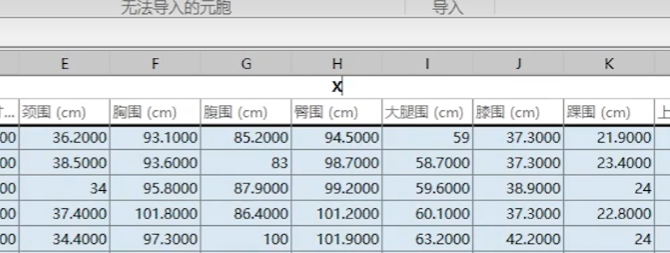

导入标签，命名为T

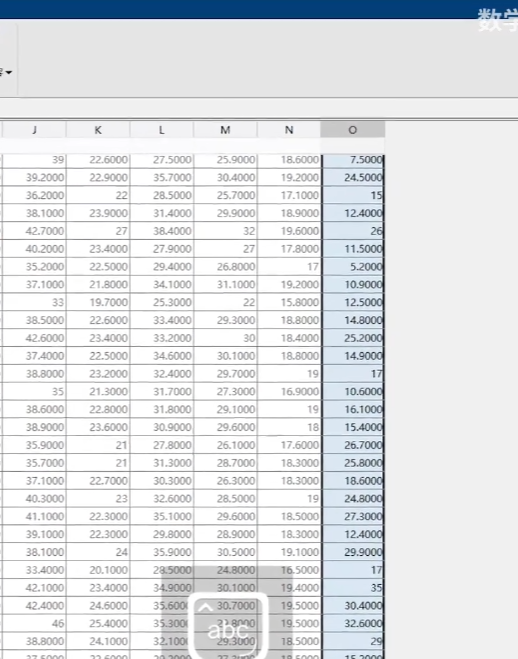

导入要预测的特征，命名XZS（张三）

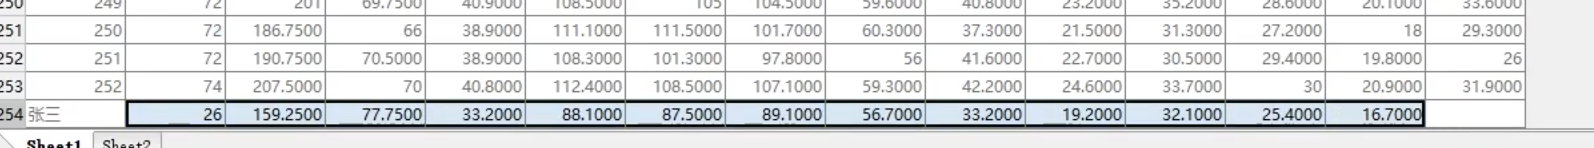

拟合神经网络工具箱

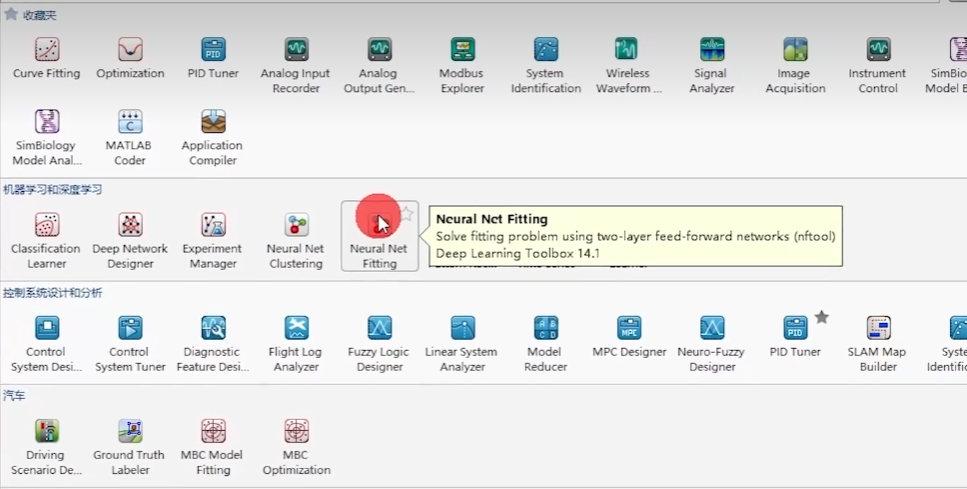

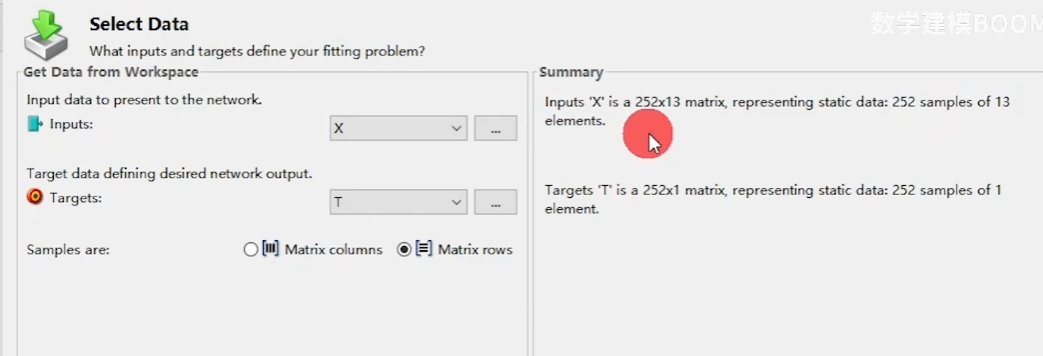

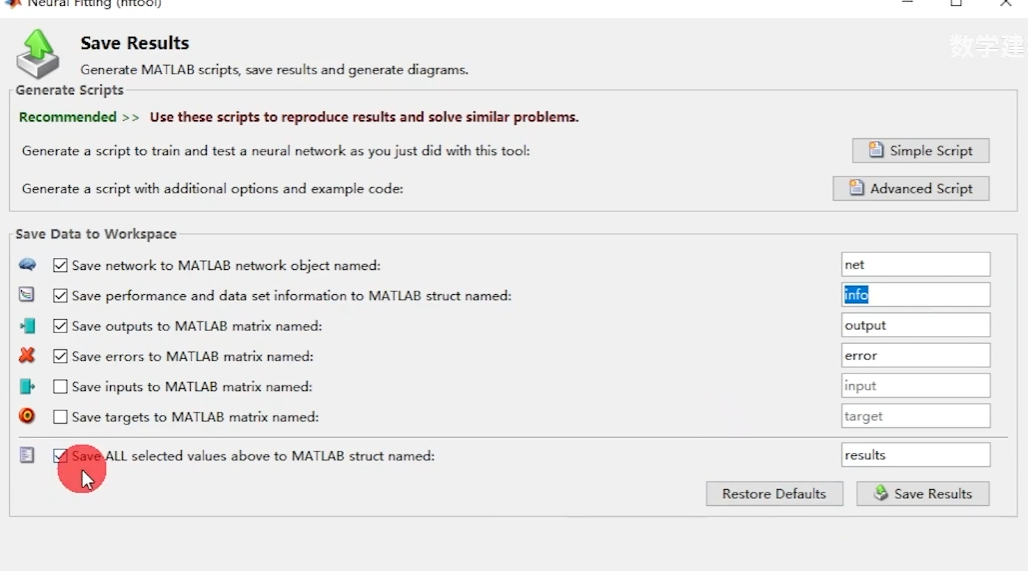

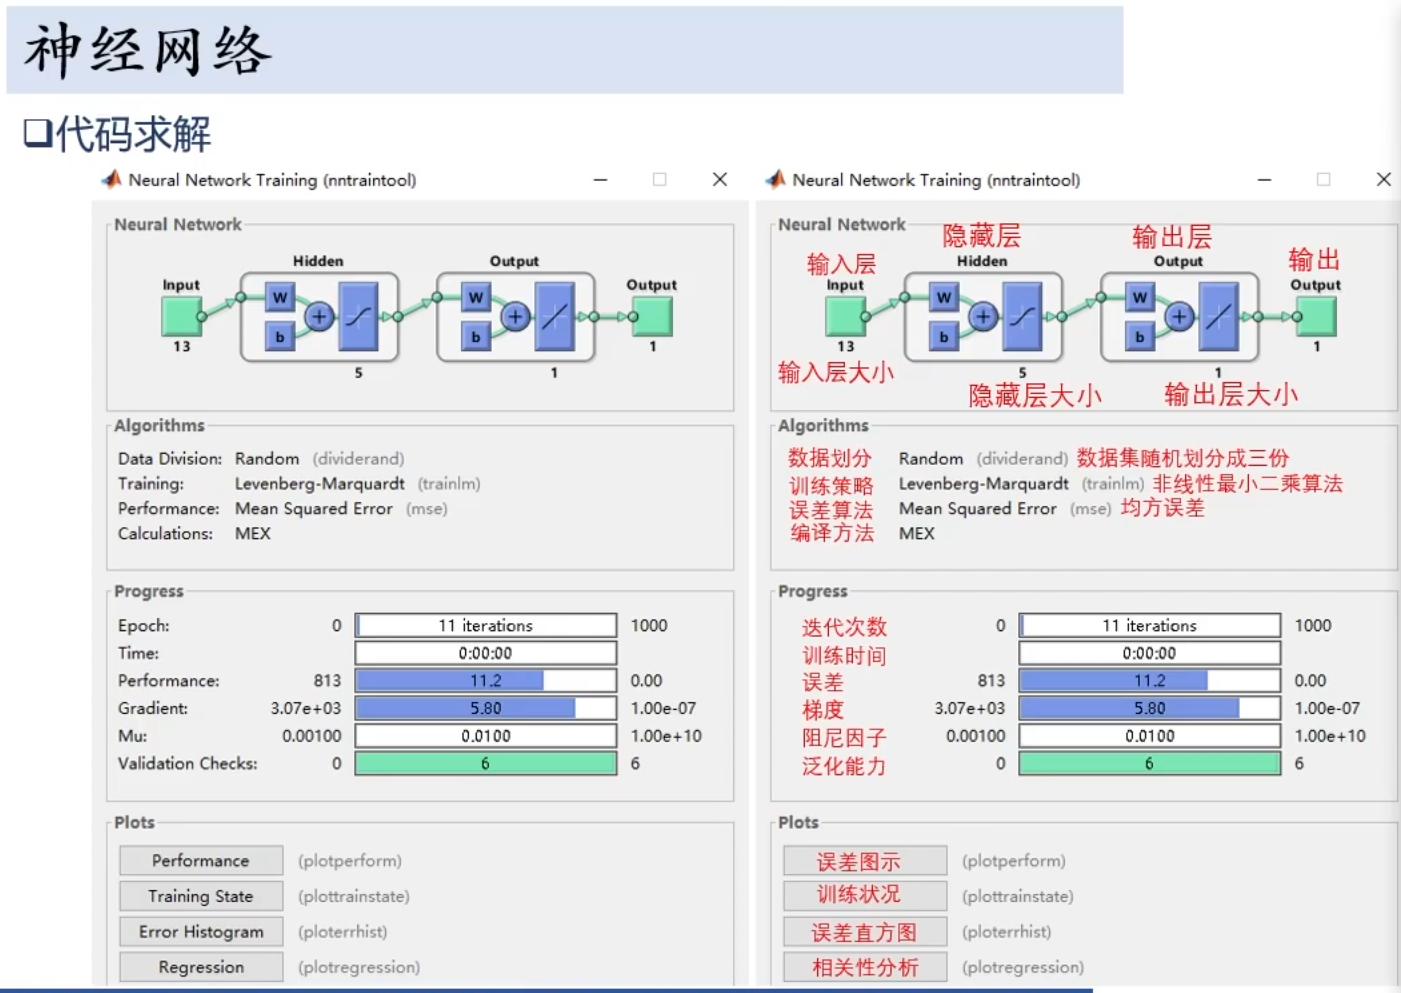

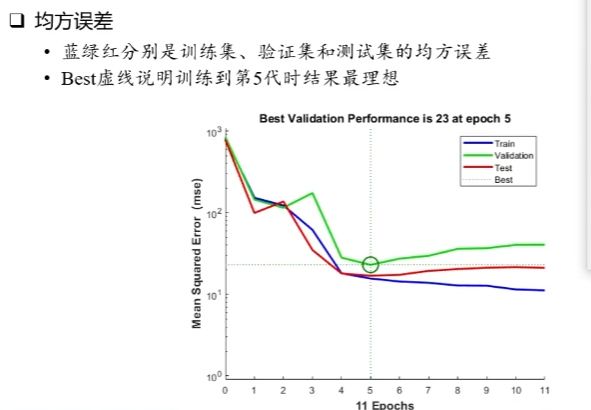

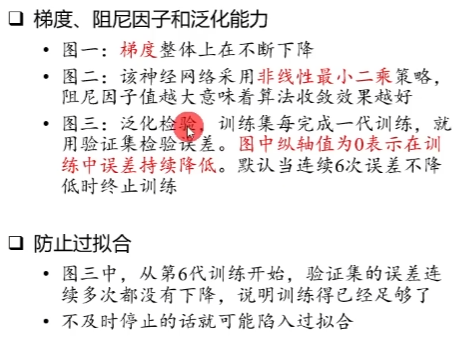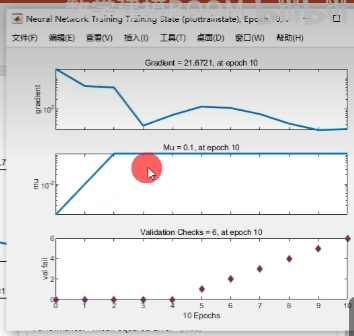

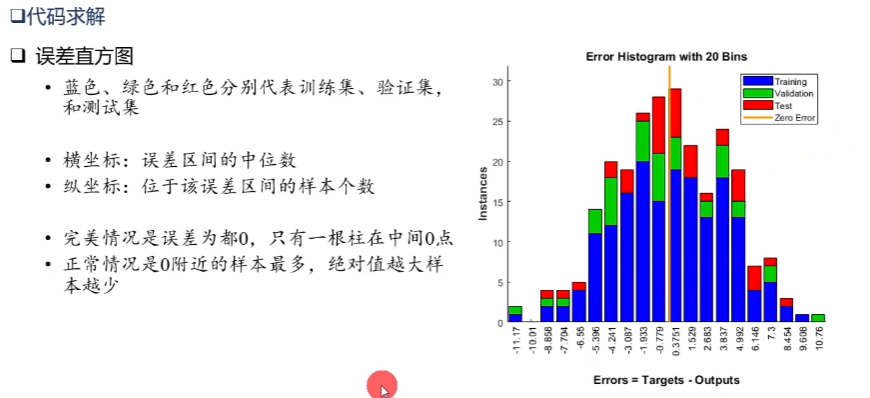

查找相关文献，与别人做的相关值作对比，评价该模型好不好

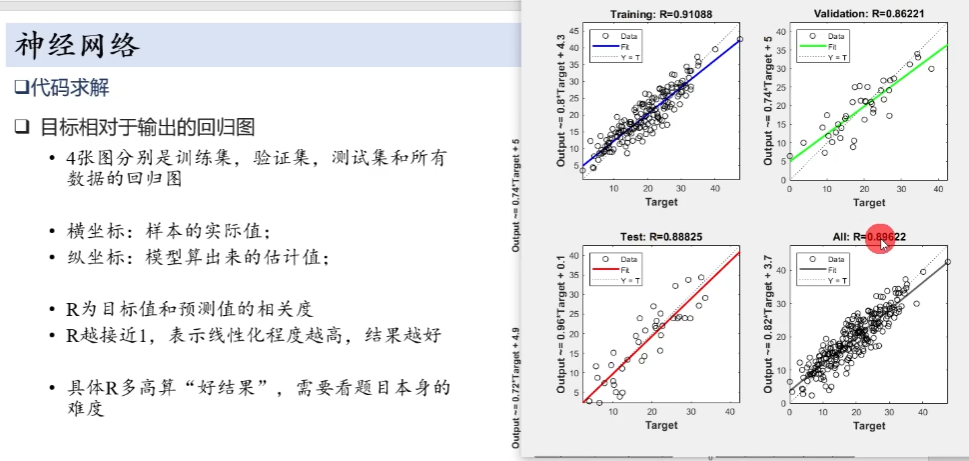

clc,clear,close all

%% 1、导入数据
% 读取excle指定范围的数据
X = table2array(readtable('NNs.xlsx','Range','B2:N253'));
T = table2array(readtable('NNs.xlsx','Range','O2:O253'));
X_zs = table2array(readtable('NNs.xlsx','Range','B254:N254'));

% 神经网络工具包语法默认需要以样本为列，所以对导入的数据进行转置
X = X'; T = T'; X_zs = X_zs';

建立前馈神经网络：

[https://ww2.mathworks.cn/help/deeplearning/ref/feedforwardnet.html](https://ww2.mathworks.cn/help/deeplearning/ref/feedforwardnet.html)

多种训练算法：

[https://ww2.mathworks.cn/help/deeplearning/ug/train-and-apply-multilayer-neural-networks.html](https://ww2.mathworks.cn/help/deeplearning/ug/train-and-apply-multilayer-neural-networks.html)

样本自动分为训练集、验证集和测试集。训练集用于对网络进行训练，只要网络针对验证集持续改进，训练就会继续。测试集提供完全独立的网络准确度测量。

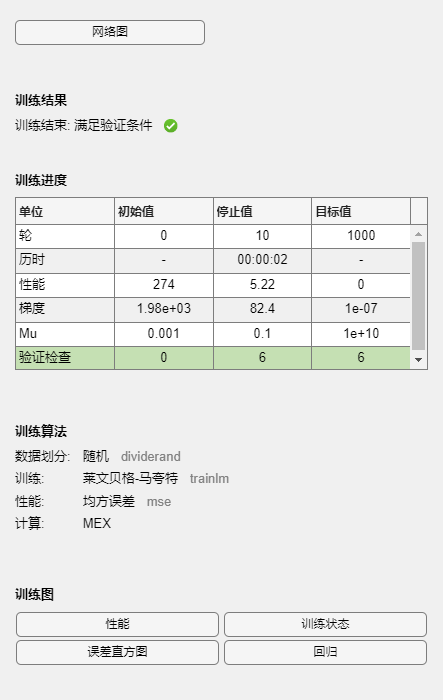

% 建立前馈神经网络，工具箱会自动把数据归一化
% 设置隐藏层
net = feedforwardnet([15,6,9]);   

% 开始训练，采用随机划分的方法把样本分为训练集、验证集和测试集
[net,tr] = train(net,X,T);  % [net,tr]分别是训练好的网络和训练记录

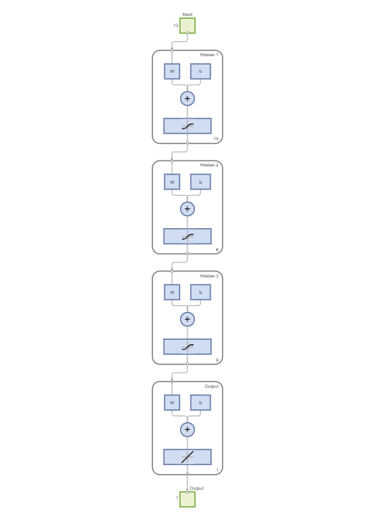


view(net)


% 求张三体脂率估计值
Y_zs = net(X_zs)

Y_zs = 21.2759



% 调用工具包极大地简化了代码，对于初学者，直接使用matlab的默认设置更稳妥
% 更多细节，例如选择训练函数、设置其他终止条件、设置样本分类比例、设置学习率初始值、权重初始值等等可手动设置

本文件出自公众号/b站：数学建模BOOM，作为售后产品供学习使用，请勿外传侵权谢谢!

更多模型算法讲解+例题+代码实现的课程，请关注公众号：数学建模BOOM，回复“课程”